# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Raisonnement pour l'analyse des synergies**

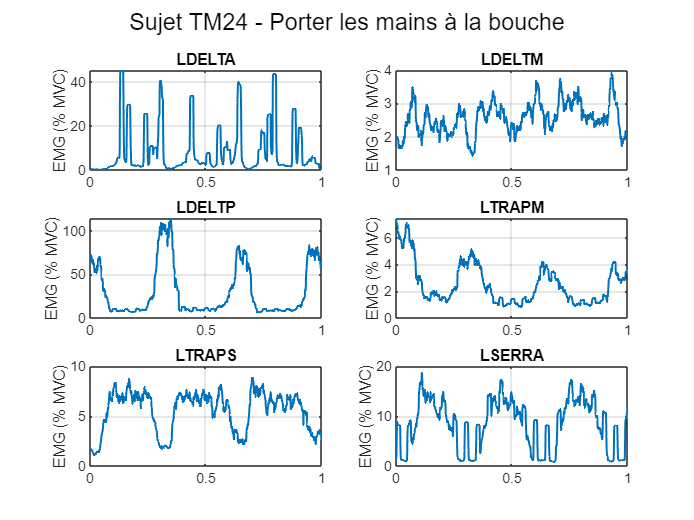

clc, clear all; 

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition sujet 
subjects = {'MG20'}; % Marche uniquement pour un sujet

% 'MF01', 'TF02', 'YL03','SC04', 'RF05', 'AP06'
% 'TD07', 'IS08', 'LC09', 'MP10', 'PK11'
% 'TF12','JM13', 'GD14', 'LD15', 'LM16','NQ17', 'JV18'
% 'EG19', 'MG20', 'LB21', 'AP22', 'SC23'
% 'TM24', 'EG25', 'RL26'
nb_subjects = length(subjects);

% Définition des muscles (choisir droite ou gauche)
% muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RSERRA'}; 
muscles = {'LDELTA', 'LDELTM', 'LDELTP', 'LTRAPM', 'LTRAPS', 'LSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};
analytic_labels = { 
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)'};

nb_functional = length(functional_labels);
nb_analytic = length(analytic_labels);

% Paramètres EMG
fs = 2000;
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass');
rms_window = round(0.250 * fs);
num_points = 1000;
time_normalized = linspace(0, 1, num_points);


% Association Muscle -> Tâche Analytique définie manuellement
assigned_analytics = [1, 2, 2, 2, 2, 2]; %4

% Initialisation des MVC des tâches analytiques
mvc = zeros(nb_muscles, 1);
all_functional_data = cell(nb_subjects, nb_functional, nb_muscles);

% Calcul du MVC basé sur la tâche analytique assignée
for subj_idx = 1:nb_subjects
    for m = 1:nb_muscles
        analytic_idx = assigned_analytics(m);
        
        fileName_analytic = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, analytic_idx);
        
        c3dH_analytic = btkReadAcquisition(fileName_analytic);
        analogs_analytic = btkGetAnalogs(c3dH_analytic);
        
        muscle_name = muscles{m};
        if isfield(analogs_analytic, muscle_name)
            signal = analogs_analytic.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            %sorted_rms = sort(emg_rms, 'descend');
            %mvc(m) = mean(sorted_rms(1:5));
            mvc(m) = max(emg_rms);
        end
    end
end

% Sélection d'une tâche fonctionnelle unique
selected_functional = input('Choisissez une tâche fonctionnelle (1-4): ');

% Traitement des données
for subj_idx = 1:nb_subjects
    fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
        '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
        subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, selected_functional);
    
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    figure;
    sgtitle(sprintf('Sujet %s - %s', subjects{subj_idx}, functional_labels{selected_functional}));
    
    for m = 1:nb_muscles
        subplot(ceil(nb_muscles/2), 2, m);
        muscle_name = muscles{m};
        if isfield(analogs_functional, muscle_name)
            signal = analogs_functional.(muscle_name);
            signal_filtered = filtfilt(b, a, signal);
            signal_abs = abs(abs(signal_filtered));
            emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
            
            % Normalisation du temps
            time_original = linspace(0, 1, length(emg_rms));
            emg_interp = interp1(time_original, emg_rms, time_normalized, 'spline');
            
            % Normalisation par le MVC associé à la tâche prédéfinie
            emg_normalized = (emg_interp / mvc(m)) * 100;

            all_functional_data{subj_idx, selected_functional, m} = emg_normalized;
            plot(time_normalized, emg_normalized, 'LineWidth', 1.2);
            title(muscle_name);
            ylabel('EMG (% MVC)');
            grid on;
        else
            title(sprintf('%s (Données absentes)', muscle_name));
        end
    end
end


%% Calcul du VAF et détermination du nombre optimal de synergies
subject_idx = 1;
functional_idx = selected_functional;

data_matrix_TF02_R = zeros(nb_muscles, num_points);
for m = 1:nb_muscles
    data_matrix_TF02_R(m, :) = all_functional_data{subject_idx, functional_idx, m};
end

disp(data_matrix_TF02_R)

    0.2848    0.2933    0.2954    0.3408    0.3365    0.3372    0.3337    0.3279    0.3244    0.3249    0.3136    0.3079    0.3115    0.3087    0.3002    0.3060    0.3006    0.3030    0.2829    0.2797    0.2688    0.2771    0.2763    0.2714    0.2724    0.2735    0.2949    0.3003    0.2883    0.2862    0.2847    0.2919    0.2915    0.2926    0.2825    0.2724    0.2581    0.2572    0.2629    0.2614    0.2631    0.2370    0.2301    0.2376    0.2355    0.2340    0.2368    0.2574    0.2489    0.2549    0.2597    0.2590    0.2622    0.2961    0.3419    0.3958    0.4154    0.4214    0.4238    0.4209    0.4277    0.4495    0.4349    0.4427    0.4387    0.4452    0.4560    0.4602    0.4491    0.4150    0.3960    0.3843    0.4302    0.6350    0.6475    0.8795    0.9255    1.0542    1.0733    1.1109    1.1763    1.3518    1.3935    1.4355    1.4778    1.5436    1.6154    1.6323    1.6154    1.6985    1.6225    1.6481    1.6443    1.6044    1.6386    1.7229    1.7105    1.7072    1.7551    1.8572

%save('C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Scripts\\SYNERGY\\SYNERGIES YOSRA\\Extraction_synergies_TF02_R.mat', 'data_matrix_TF02_R');
%save('C:\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Scripts\\DATA\\Extraction_synergies_MF01_R.mat', 'data_matrix_MF01_R');

% Paramètres pour le calcul du VAF
max_synergies = min(10, nb_muscles);   % On teste jusqu'à 10 synergies ou le nombre de muscles
VAF_threshold = 0.90;                   % Seuil de VAF à atteindre (90%)
VAF_values = zeros(1, max_synergies);   % Pour stocker le VAF calculé pour chaque nombre de synergies
optimal_synergies = max_synergies;       % Valeur par défaut si le seuil n'est jamais atteint
foundOptimal = false;                   % Indique si le seuil a été dépassé pour la première fois

% Paramètres pour le calcul du VAF musculaire
VAF_m_threshold = 0.80;  % Seuil individuel pour chaque muscle
VAF_m_values = zeros(nb_muscles, max_synergies);  % Stocker les VAF individuels

% Options NNMF
options = statset('MaxIter', 1000, 'Display', 'off');

% Boucle pour la décomposition NNMF et le calcul du VAF
for s = 1:max_synergies
    % Décomposition NNMF pour s synergies
    [W, H] = nnmf(data_matrix_TF02_R, s, 'Options', options);
    
    % Reconstruction du signal
    X_reconstructed = W * H;
    
    % Calcul du VAF général
    VAF_values(s) = 1 - (sum(sum((data_matrix_TF02_R - X_reconstructed).^2)) / sum(sum(data_matrix_TF02_R.^2)));

    % Calcul du VAF musculaire pour chaque muscle
    for m = 1:nb_muscles
        VAF_m_values(m, s) = 1 - (sum((data_matrix_TF02_R(m, :) - X_reconstructed(m, :)).^2) / sum(data_matrix_TF02_R(m, :).^2));
    end
    
    % Vérification du seuil VAF global + VAF musculaire
    if (VAF_values(s) >= VAF_threshold) && all(VAF_m_values(:, s) >= VAF_m_threshold) && (~foundOptimal)
        optimal_synergies = s;
        foundOptimal = true;
    end
end


% Affichage des résultats
fprintf('Nombre optimal de synergies (VAF global et musculaire) pour le sujet %s et la tâche %s : %d\n', ...
    subjects{subject_idx}, functional_labels{functional_idx}, optimal_synergies);

Nombre optimal de synergies (VAF global et musculaire) pour le sujet GD14 et la tâche Porter les mains le plus haut possible au-dessus de la tête : 3


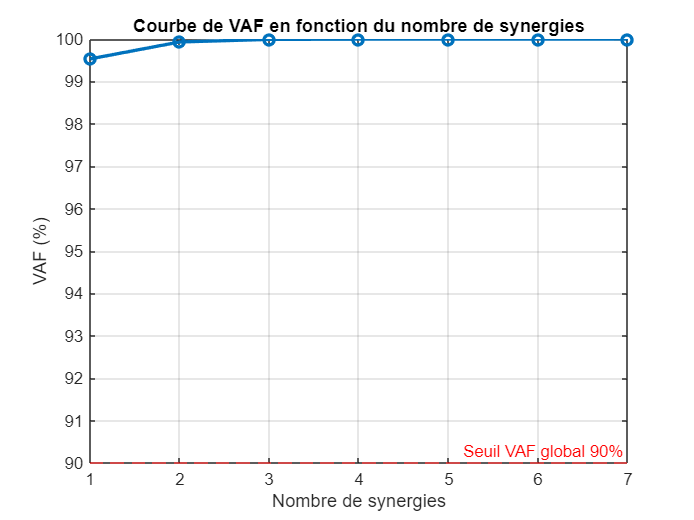


% Tracé du VAF général
figure;
plot(1:max_synergies, VAF_values * 100, '-o', 'LineWidth', 2);
hold on;
yline(VAF_threshold * 100, 'r--', 'Seuil VAF global 90%');
xlabel('Nombre de synergies');
ylabel('VAF (%)');
title('Courbe de VAF en fonction du nombre de synergies');
grid on;

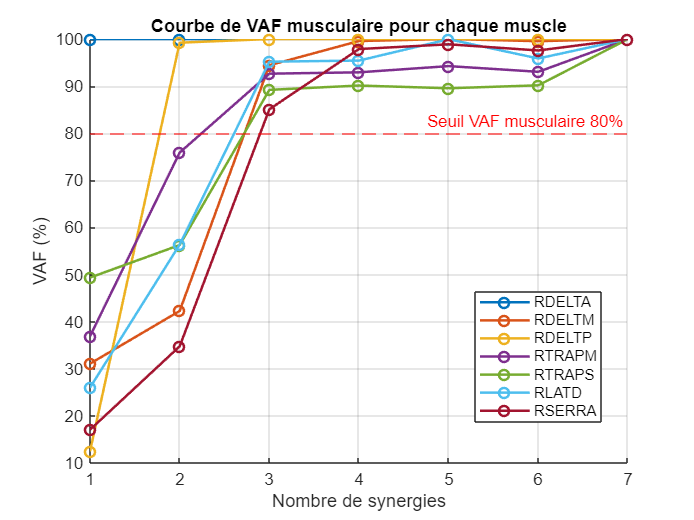


% Tracé du VAF musculaire pour chaque muscle
figure;
hold on;
for m = 1:nb_muscles
    plot(1:max_synergies, VAF_m_values(m, :) * 100, '-o', 'LineWidth', 1.5);
end
yline(VAF_m_threshold * 100, 'r--', 'Seuil VAF musculaire 80%');
xlabel('Nombre de synergies');
ylabel('VAF (%)');
title('Courbe de VAF musculaire pour chaque muscle');
grid on;
legend(muscles, 'Location', 'best'); % Ajouter une légende avec les noms des muscles

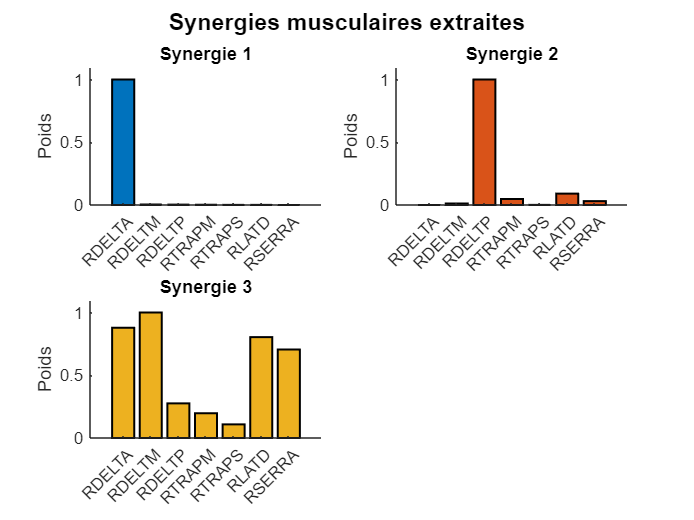


%% Visualisation des synergies musculaires extraites
% Recalcul de la décomposition NNMF avec le nombre optimal de synergies
[W, H] = nnmf(data_matrix_TF02_R, optimal_synergies, 'Options', options);

% Optionnel : Normalisation de chaque colonne de W pour obtenir des valeurs entre 0 et 1
W_norm = zeros(size(W));
for i = 1:size(W,2)
    if max(W(:, i)) ~= 0
        W_norm(:, i) = W(:, i) / max(W(:, i));
    else
        W_norm(:, i) = W(:, i);
    end
end

% Visualisation : affichage des poids de chaque synergie
figure;
sgtitle('Synergies musculaires extraites', 'FontSize', 14, 'FontWeight', 'bold');

colors = lines(optimal_synergies); % Palette de couleurs

for i = 1:optimal_synergies
    subplot(ceil(optimal_synergies/2), 2, i);
    b = bar(W_norm(:, i), 'FaceColor', colors(i, :), 'EdgeColor', 'k', 'LineWidth', 1.2);
    title(['Synergie ', num2str(i)], 'FontSize', 12, 'FontWeight', 'bold');
    xticks(1:nb_muscles);
    xticklabels(muscles);
    xtickangle(45);
    ylabel('Poids', 'FontSize', 12);
    ylim([0, max(W_norm(:)) * 1.1]); % Uniformisation des axes
    set(gca, 'FontSize', 10, 'Box', 'off'); % Amélioration de l'esthétique des axes
end

% Ajustement de l'affichage
set(gcf, 'Position', [100, 100, 800, 600]); % Ajustement de la taille de la figure

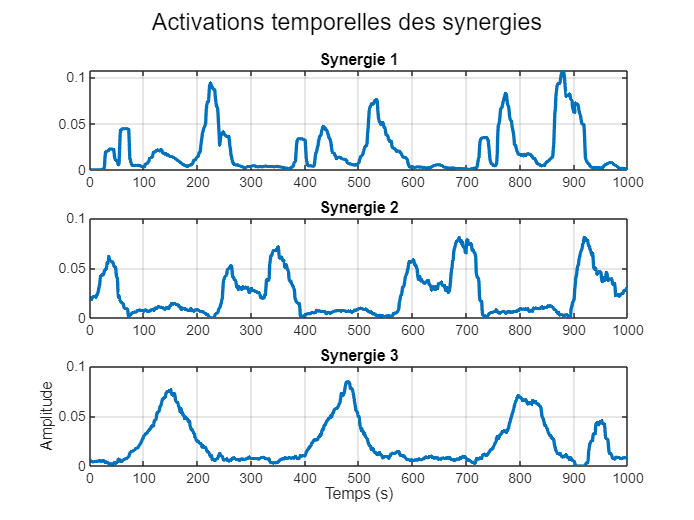


% Visualisation des activations temporelles des synergies

C = H;  % Activation temporelle des synergies

figure;
set(gcf, 'Name', 'Étape 6', 'NumberTitle', 'off');
sgtitle('Activations temporelles des synergies');

for i = 1:optimal_synergies
    subplot(optimal_synergies, 1, i);
    plot(C(i, :), 'LineWidth', 2);
    title(['Synergie ', num2str(i)]);
    grid on;
end
xlabel('Temps (s)');
ylabel('Amplitude');